# 4.3 Finite data records

Alexandre Rey, MSE, MA-StatDig, 2022

clear;
rng default;

addpath('../functions/');

## Exemple with a sinus signal

We want to modelize with a all pole second order model:

$H(z)=\frac{b(0)}{1+a(1)z^{-1}+a(2)z^{-2}$   (1)

The normal equation are:

$\left[\matrix{r_x(0) & r_x(1) \cr r_x(1) & r_x(0)}\right]\left[\matrix{a(1) \cr a(2)}\right] = \left[\matrix{r_x(1) \cr r_x(2)} \right]$  (2)


$$R_x\overline{a}_p = -r_x$$


## Theoric value of the autocorrelation and Prony computed all pole filter

The theoric autocorrelation of $x(n)$are given by (see example 3.3.1 in chapter 3):

$r_x(k) = E\{x(n)x(n-k)\} = \lim_{N\rightarrow \infty}\frac{1}{N}\sum_{n=k}^Nx(n)x(n-k)=\frac{1}{2}A^2\cos(k\omega_0)$   (3)

Try several number odd samples $N$, for a multiple of the period length (ex 40) and also 38, 42 or 55. The result will be very different to the theory.

N = 55;     % number of samples
n = 0:N-1;
N0 = 20;  
A = 1;      % amplitude

x = A .* sin(n * 2*pi/N0);
x = x(:);

x =          0
    0.3090
    0.5878
    0.8090
    0.9511
    1.0000
    0.9511
    0.8090
    0.5878
    0.3090


%dn = zeros(1,N);
%dn(1) = 1;
p = 2;

If we compare with the theoric values of the autocorrelation (3) we have the values $r_x(k)$ for $k = 0,1,2$:

% theoric autocorrelation (see ex. 3.3.1)
rx_th = 0.5 * A.^2 * cos((0:p) * 2*pi/N0);

rx_th =     0.5000    0.4755    0.4045


% theoric autocorrelation matrix
Rx_th = toeplitz(rx_th(1:p), rx_th(1:p));

Rx_th =     0.5000    0.4755
    0.4755    0.5000


% denominator coefficients a
ap_th = [1; -Rx_th\rx_th(2:p+1)']; % a[0], a[1], a[2]

ap_th =     1.0000
   -1.9021
    1.0000


% minimum error epsilon_p
Ep_th = rx_th(1) + rx_th(2:p+1)*ap_th(1:p); % faux

Ep_th = 0.2061

% poles roots
p_th = roots(ap_th);

p_th =    0.9511 + 0.3090i
   0.9511 - 0.3090i


As expected the norm of the poles is $= 1$, that produces an impulse response $h(n) = x(n)$.


$$H(z) = \frac{b(0)}{1+a(1)z^{-1}+a(2)z^{-2}} \Rightarrow y[n] = b(0)x[n] - a(1)y[n-1] - a(2)y[n-2] \Rightarrow b(0) = x[2]$$


Norm_pth = abs(p_th);

Norm_pth =     1.0000
    1.0000


b_th = x(2);

b_th = 0.3090

H_th = tf(b_th, ap_th', 1)

H_th =
 
        0.309
  -----------------
  z^2 - 1.902 z + 1
 
Sample time: 1 seconds
Discrete-time transfer function.



h_th = impz(b_th, ap_th, length(x))';

h_th =     0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090   -0.0000   -0.3090   -0.5878   -0.8090   -0.9511   -1.0000   -0.9511   -0.8090   -0.5878   -0.3090    0.0000    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090   -0.0000   -0.3090   -0.5878   -0.8090   -0.9511   -1.0000   -0.9511   -0.8090   -0.5878   -0.3090    0.0000    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090   -0.0000


figure;
    plot(n, x, '.-', ...
         n, h_th, '.-');
    grid;
    legend('x(n)', 'h(n)_{theoric}')
    xlabel('n')

% theoretical anticipates perfectly

## Autocorrelation method to estimate the all pole filter

The estimation of the autocorrelation as the Prony Autocorrelation method is different:

$\hat{r}_x(k)=\frac{1}{N}\sum_{n=k}^Nx(n)x(n-k)\qquad ; k \ge  0$    (4)

To estimate the autocorrelation with a finite record of $N$ points we use the convolution matrix:

X = convmtx(x, p+1);

X =          0         0         0
    0.3090         0         0
    0.5878    0.3090         0
    0.8090    0.5878    0.3090
    0.9511    0.8090    0.5878
    1.0000    0.9511    0.8090
    0.9511    1.0000    0.9511
    0.8090    0.9511    1.0000
    0.5878    0.8090    0.9511
    0.3090    0.5878    0.8090


Xp = X(1:N+p-1, 1:p);

Xp =          0         0
    0.3090         0
    0.5878    0.3090
    0.8090    0.5878
    0.9511    0.8090
    1.0000    0.9511
    0.9511    1.0000
    0.8090    0.9511
    0.5878    0.8090
    0.3090    0.5878


Rx = Xp' * Xp .* 1/N;

Rx =     0.4909    0.4582
    0.4582    0.4909


rx = Xp'*X(2:N+p, 1) .* 1/N;

rx =     0.4582
    0.3824


% prefix _acm for autocorrelation method
ap_acm = [1; -Rx\rx]; % a[0] a[1] a[2]

ap_acm =     1.0000
   -1.6027
    0.7170


Error:


$$\epsilon_p = r_x(0)+\sum_{k=1}^pa_p(k)r_x^*(k)$$
 

% minimum error of the model (4p22)
err_acm = (Rx(1,1) + rx'*ap_acm(2:3)) * N;

err_acm = 1.6882

bq0_acm = sqrt(err_acm);

bq0_acm = 1.2993

The poles of the transfer function are:

poles_acm = roots(ap_acm);

poles_acm =    0.8014 + 0.2735i
   0.8014 - 0.2735i


We see the norm of  the poles are $< 1$, filter is stable but the impulse response $h(n)$ is the damped sinus...

Norm_p = abs(poles_acm);

Norm_p =     0.8468
    0.8468


H_acm = tf(bq0_acm, ap_acm', 1);

H_acm =
 
          1.299
  ---------------------
  z^2 - 1.603 z + 0.717
 
Sample time: 1 seconds
Discrete-time transfer function.



h_acm = impz(bq0_acm, ap_acm, length(x))'

h_acm =     1.2993    2.0825    2.4060    2.3630    2.0622    1.6108    1.1031    0.6130    0.1916   -0.1325   -0.3497   -0.4655   -0.4953   -0.4601   -0.3823   -0.2828   -0.1791   -0.0843   -0.0067    0.0497    0.0844    0.0997    0.0993    0.0876    0.0692    0.0482    0.0275    0.0096   -0.0044   -0.0139   -0.0191   -0.0207   -0.0194   -0.0163   -0.0122   -0.0079   -0.0039   -0.0006    0.0019    0.0034    0.0041    0.0042    0.0037    0.0030    0.0021    0.0012    0.0005   -0.0001   -0.0005   -0.0008


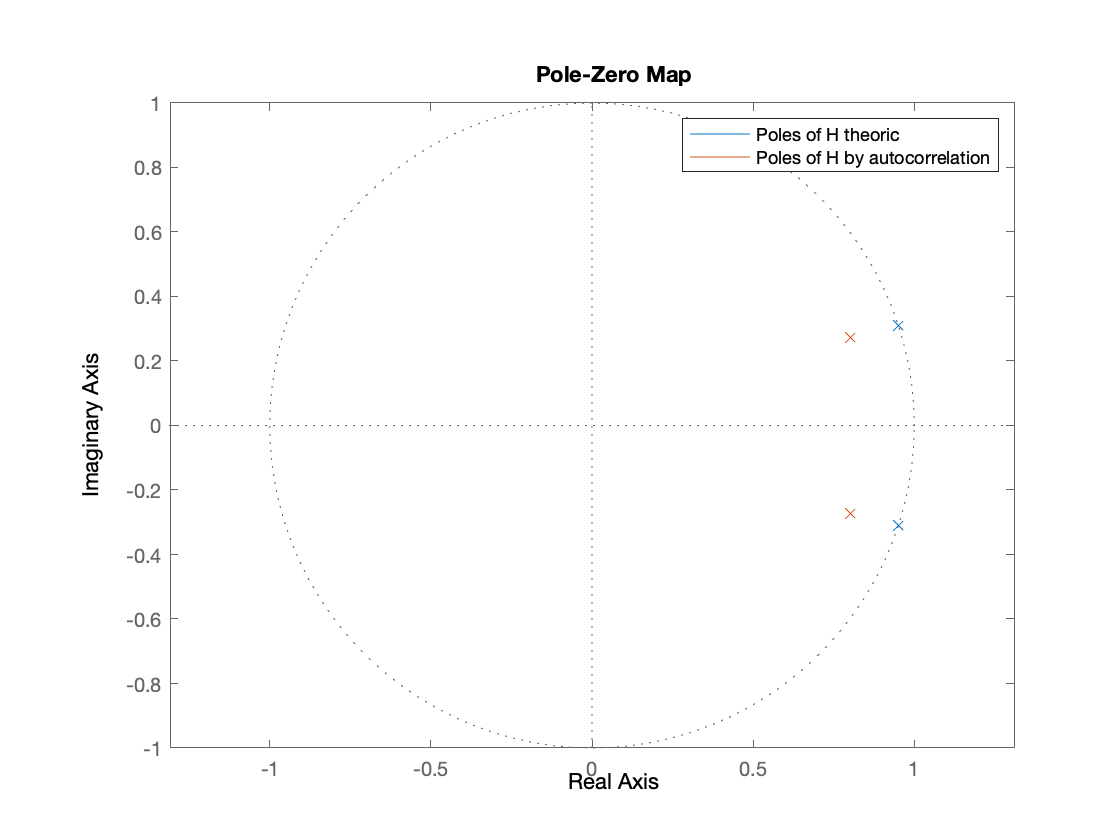

figure;
    pzplot(H_th, H_acm)
    legend('Poles of H theoric', ...
           'Poles of H by autocorrelation');
    axis equal

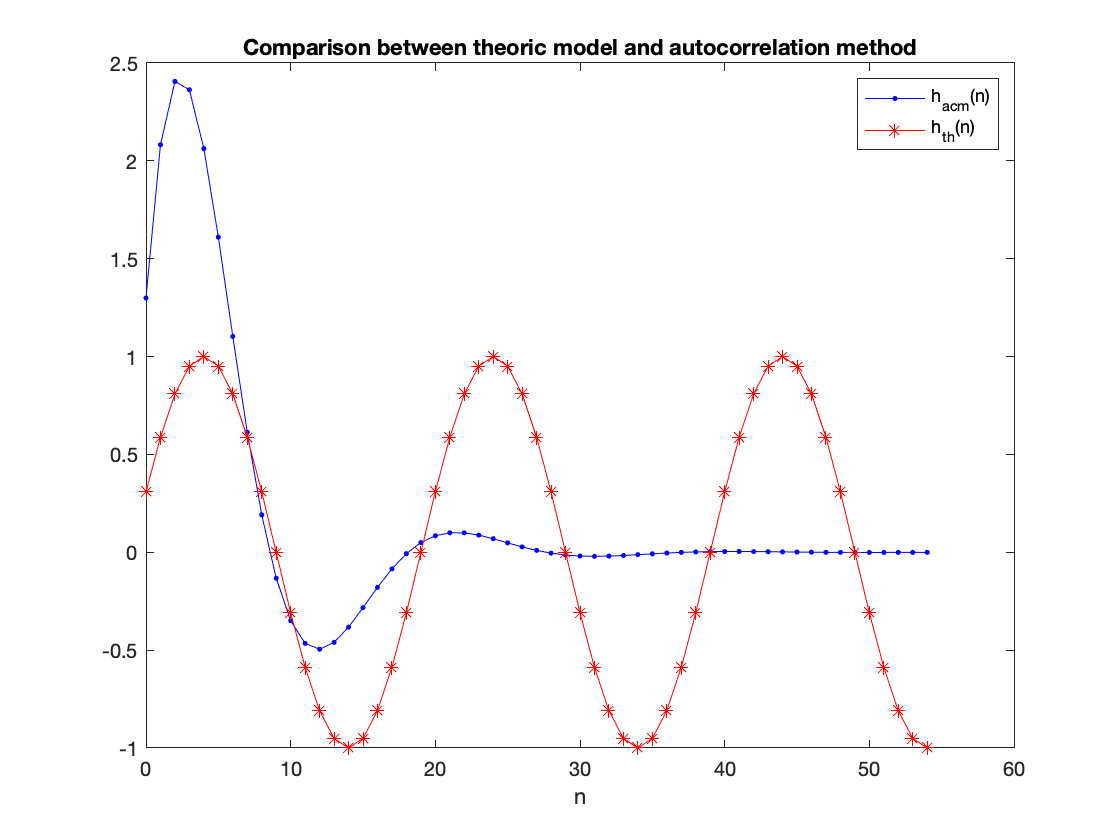

figure;
    plot(n, h_acm, '.-b', ...
         n, h_th, '*-r');
    legend('h_{acm}(n)', 'h_{th}(n)');
    title('Comparison between theoric model and autocorrelation method');
    xlabel('n');

## Covariance Method to estimate the all pole filter

Now try with the Covariance method:


$$\hat{r}_{xcov}(k,l) = \frac{1}{N}\sum_{n=p}^{N}x(n-l)x(n-k)$$


we compute the autocorrelation matrix with the convm:

Xp_cov = X(p:N-1, 1:p);

Xp_cov =     0.3090         0
    0.5878    0.3090
    0.8090    0.5878
    0.9511    0.8090
    1.0000    0.9511
    0.9511    1.0000
    0.8090    0.9511
    0.5878    0.8090
    0.3090    0.5878
    0.0000    0.3090


xp = X(p+1:N, 1);
Rx_cov = Xp_cov' * Xp_cov * 1/N;

Rx_cov =     0.4745    0.4442
    0.4442    0.4626


rx_cov = Xp_cov' * xp * 1/N;

rx_cov =     0.4582
    0.3824


ap_cov = [1; -inv(Rx_cov)*rx_cov];

ap_cov =     1.0000
   -1.9021
    1.0000


%err_cov = 7.1054e-15 ?!
%bq0_cov = 8.4294e-08 ?!
bq0_th = x(2);

The poles of the transfert function are:

poles_cov = roots(ap_cov);

poles_cov =    0.9511 + 0.3090i
   0.9511 - 0.3090i


Norm_p_cov = abs(poles_cov);

Norm_p_cov =     1.0000
    1.0000


H_cov = tf(bq0_th, ap_cov', 1)

H_cov =
 
        0.309
  -----------------
  z^2 - 1.902 z + 1
 
Sample time: 1 seconds
Discrete-time transfer function.



h_cov = impz(bq0_th, ap_cov, length(x))'

h_cov =     0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090    0.0000   -0.3090   -0.5878   -0.8090   -0.9511   -1.0000   -0.9511   -0.8090   -0.5878   -0.3090   -0.0000    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090    0.0000   -0.3090   -0.5878   -0.8090   -0.9511   -1.0000   -0.9511   -0.8090   -0.5878   -0.3090   -0.0000    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090    0.0000


## Models compare: Theory, Autocorrelation method and Covariance method

figure;
    pzplot(H_th, H_acm, H_cov);
    legend('Poles of H theoric', ...
           'Poles of H by autococorrelation', ...
           'Poles of H by covariance');
    axis equal;

If the estimation of the autocorrelation $r_x$ is not accurate (because $N$ is not bigger enough or is not a multiple of the periode length) the poles given by the autocorrelation method is not well estimated giving a damped sinus impulse response:

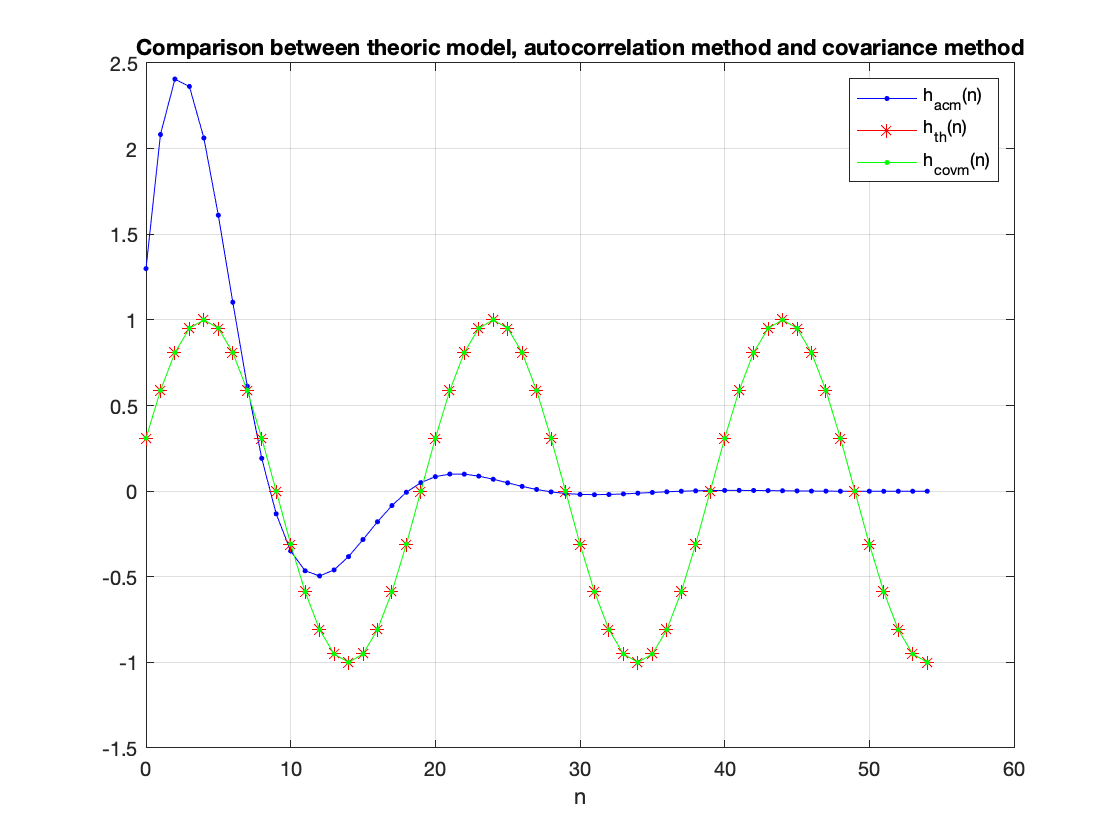

figure;
    plot(n, h_acm, '.-b', ...
         n, h_th, '*-r', ...
         n, h_cov, '.-g');
    legend('h_{acm}(n)', 'h_{th}(n)', 'h_{covm}(n)');
    title('Comparison between theoric model, autocorrelation method and covariance method');
    xlabel('n');
    grid on;

## Test of the AutoCorrelation function with some examples

### Impulse response

Test the fuction with a finite data record and find an all pole 2nd order model:


$$H(z) = \frac{b(0)}{1+a(1)z^{-1}+a(2)z^{-2}}$$


with the signal $x(n)$ defined as:

N = 50;
n = 0:N-1;
x = (-1).^n .* ones(1,N)

x =      1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1     1    -1


p = 2;
[ap_acm, bq0_acm, err_acm] = acm(x, p)

ap_acm =     1.0000
    0.9899
    0.0101


bq0_acm = 1.4071

err_acm = 1.9798

[ap_covm, bq0_covm, err_covm] = covm(x, p)

ap_covm =     1.0000
    0.5000
   -0.5000


bq0_covm = 1

err_covm = 4.7923e-29

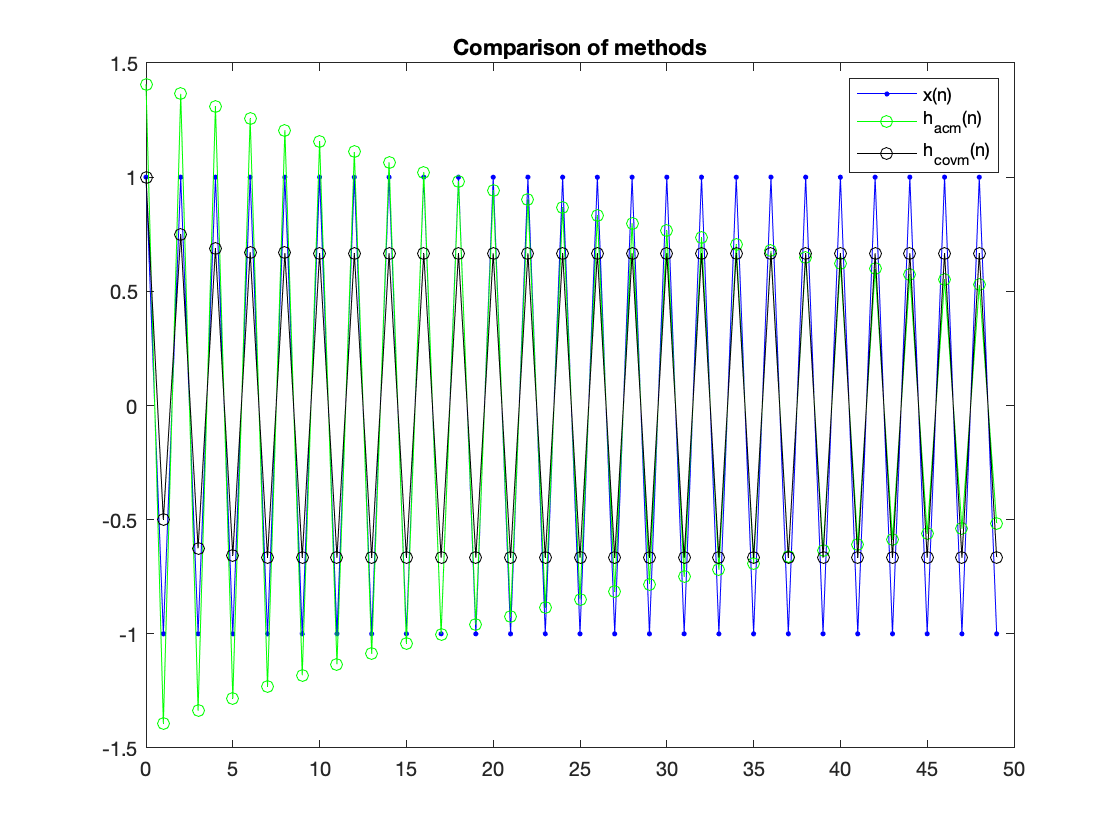

h_acm = impz(bq0_acm, ap_acm, length(x))';
h_covm = impz(bq0_covm, ap_covm, length(x))';

figure;
    plot(n, x, '.-b', ...
         n, h_acm, 'o-g', ...
         n, h_covm, 'o-k');
    title('Comparison of methods');
    legend('x(n)', 'h_{acm}(n)', 'h_{covm}(n)');

### Exemple with a noisy signal

N = 400;
n = 0:N-1;
N0 = 20;
A = 1;
x = A .* sin(n * 2*pi/N0)

x =          0    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090    0.0000   -0.3090   -0.5878   -0.8090   -0.9511   -1.0000   -0.9511   -0.8090   -0.5878   -0.3090   -0.0000    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090    0.0000   -0.3090   -0.5878   -0.8090   -0.9511   -1.0000   -0.9511   -0.8090   -0.5878   -0.3090   -0.0000    0.3090    0.5878    0.8090    0.9511    1.0000    0.9511    0.8090    0.5878    0.3090


Sigman = 0.05;
xn = x + Sigman*randn(1,N)

xn =     0.0269    0.4007    0.4748    0.8521    0.9670    0.9346    0.9294    0.8261    0.7667    0.4475   -0.0675   -0.1573   -0.5515   -0.8122   -0.9153   -1.0102   -0.9573   -0.7345   -0.5173   -0.2382    0.0336    0.2486    0.6236    0.8905    0.9755    1.0517    0.9874    0.7938    0.6025    0.2697    0.0444   -0.3664   -0.6412   -0.8495   -1.0983   -0.9281   -0.9348   -0.8468   -0.5193   -0.3946   -0.0051    0.2969    0.6037    0.8247    0.9078    0.9985    0.9428    0.8404    0.6424    0.3645


We want to find a second order model (2 poles) with acm:

p = 2;
[ap_acm2, bq0_acm2, err_acm2] = acm(xn, p)

ap_acm2 =     1.0000
   -1.7479
    0.8477


bq0_acm2 = 2.4565

err_acm2 = 6.0346

[ap_covm2, bq0_covm2, err_covm2] = covm(xn, p)

ap_covm2 =     1.0000
   -1.7506
    0.8507


bq0_covm2 = 1

err_covm2 = 5.8540

The pole-zero map is:

H_com = tf(bq0_acm2, ap_acm2', 1)

H_com =
 
          2.457
  ----------------------
  z^2 - 1.748 z + 0.8477
 
Sample time: 1 seconds
Discrete-time transfer function.



H_acm = tf(bq0_covm2, ap_covm2', 1)

H_acm =
 
            1
  ----------------------
  z^2 - 1.751 z + 0.8507
 
Sample time: 1 seconds
Discrete-time transfer function.



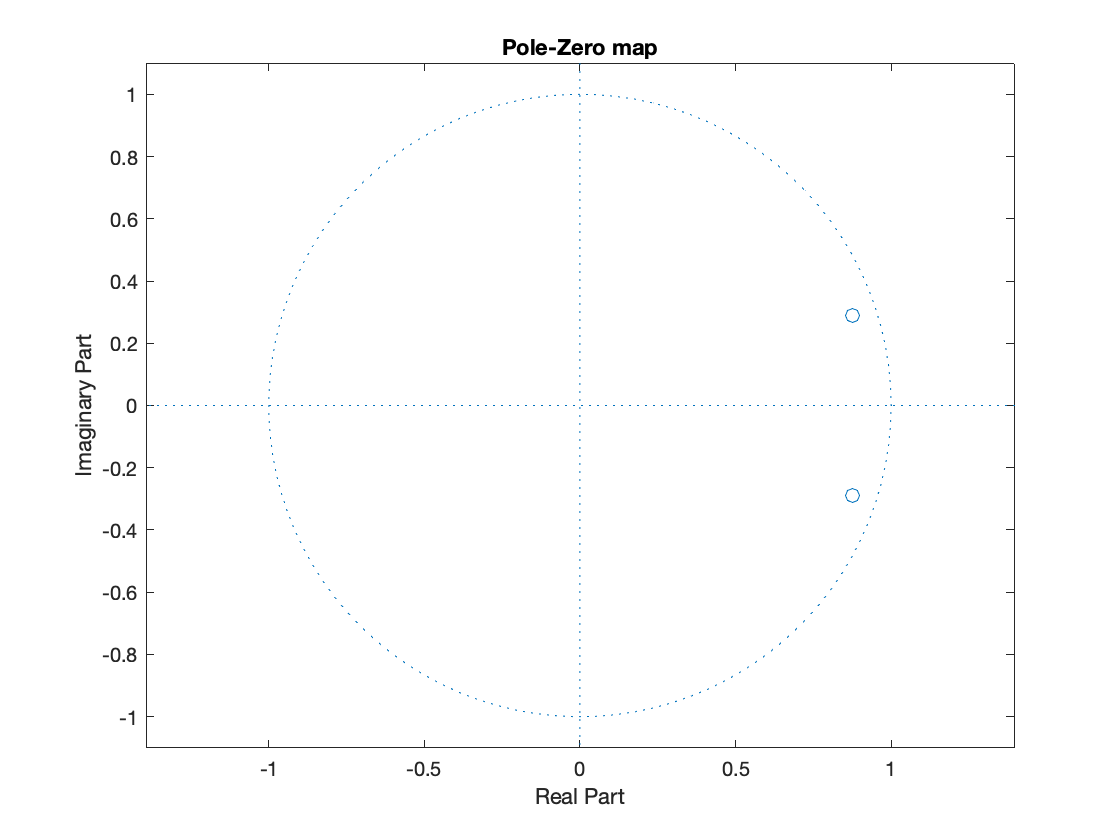

figure;
    roots_acm = roots(ap_covm2);
    zplane(roots_acm);
    title('Pole-Zero map')

h_acm2 = impz(bq0_acm2, ap_acm2, length(x))'

h_acm2 =     2.4565    4.2937    5.4223    5.8376    5.6068    4.8512    3.7262    2.4005    1.0369   -0.2225   -1.2680   -2.0276   -2.4691   -2.5968   -2.4457   -2.0734   -1.5508   -0.9529   -0.3509    0.1945    0.6374    0.9492    1.1188    1.1508    1.0630    0.8824    0.6412    0.3728    0.1079   -0.1273   -0.3141   -0.4410   -0.5046   -0.5081   -0.4603   -0.3738   -0.2632   -0.1432   -0.0271    0.0740    0.1523    0.2035    0.2266    0.2235    0.1986    0.1576    0.1072    0.0537    0.0030   -0.0403


h_covm2 = impz(bq0_covm2, ap_covm2, length(x))'

h_covm2 =     1.0000    1.7506    2.2138    2.3863    2.2942    1.9862    1.5253    0.9806    0.4191   -0.1005   -0.5325   -0.8467   -1.0292   -1.0814   -1.0176   -0.8614   -0.6424   -0.3918   -0.1393    0.0894    0.2749    0.4053    0.4756    0.4878    0.4494    0.3717    0.2684    0.1537    0.0407   -0.0595   -0.1388   -0.1923   -0.2186   -0.2191   -0.1976   -0.1595   -0.1111   -0.0589   -0.0085    0.0352    0.0688    0.0905    0.1000    0.0980    0.0865    0.0680    0.0455    0.0218   -0.0005   -0.0195
